# Payload Carrying Quad Rotor Drone Optimization

## Project purpose:

We set our payload goal as 70 lbs because that is the maximum standard parcell weight carried by the USPS, in order to ground the project in a real world operating condition.

## Understanding thrust relationships in dynamic and static conditions:

We initially started off by trying to understand the relationships between propellor RPM, thrust generated, and incoming airstream velocity to build towards being able to simulate dynamic flight conditions.

Good quality data on propellor performance that included this information was obtained from APC Propellors, a company that makes propellors for drones/model aircraft as well as marine applications, and we built a function to read in their data files and plot the relevant information.

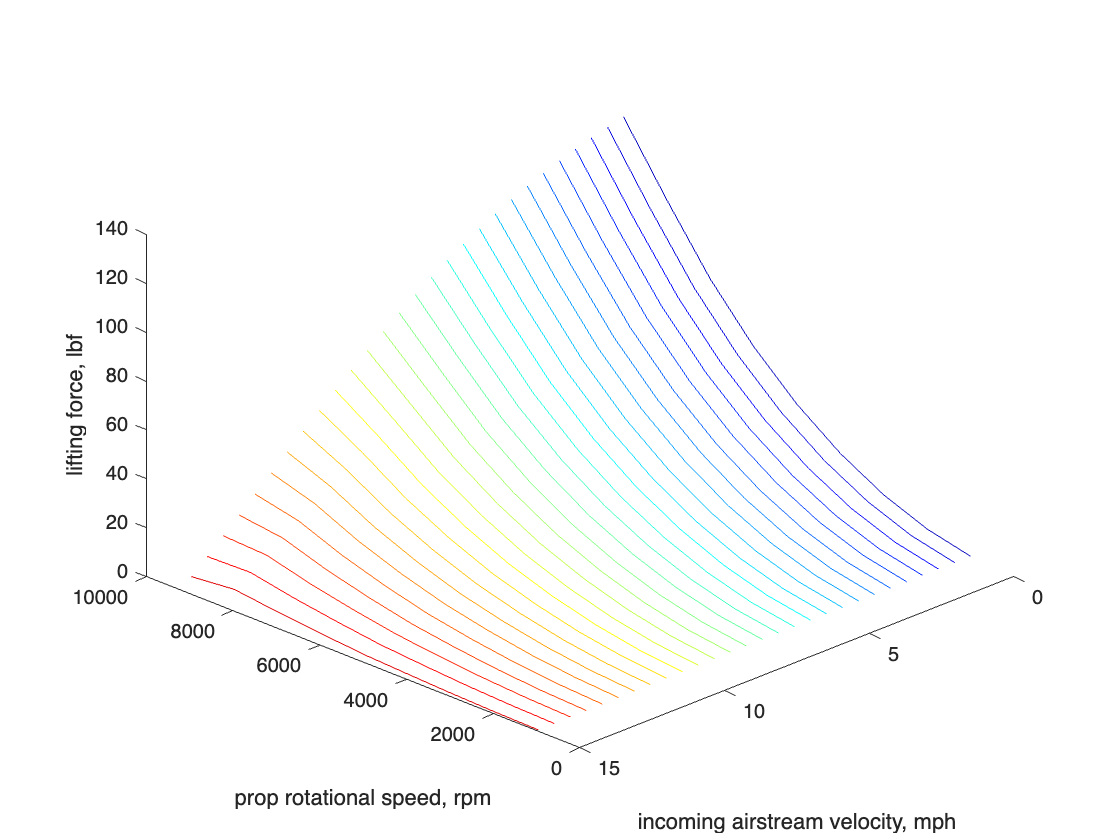

%plots thrust vs. incoming airstream velocity for various RPMs
propplot('PER3_27x13E.dat')

### **Above plot: rpm-incoming airstream velocity-lifting force relationship for a 27 inch diameter 13 inch pitch propellor manufacted by APC Propellors**

For the purposes of designing an optimized quad rotor drone airframe, we decided that looking for data from motor-propellor combinations would be the easiest approach, due to difficulties we ran into in integrating independent data sets from motors and propellors. In our case, we selected the Xoar TA110-20 KV80 motor due to available data that indicated it would meet the thrust requirements.

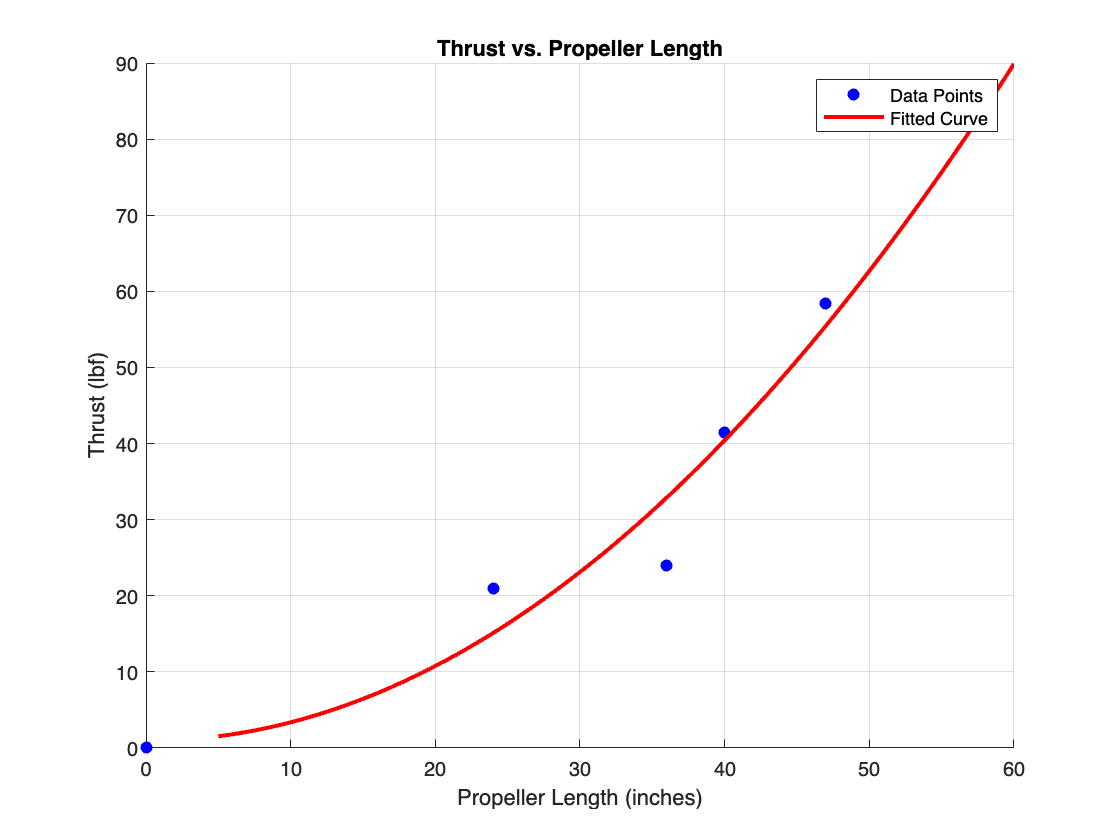

%plotting fitted curve, discrete datapoints, for Xoar TA110-20 KV80 motor combined with various length propellors
thrustvproplen

### **Above plot: Thrust vs. Propellor Length for **Xoar TA110-20 KV80 motor utilizing **various propellors, curve fit**

## Guiding Factors for Airframe Design:

The primary driving factor for the motor arm length is propellor clearance. This is both determined by the fact that the propellors must not overlap to prevent collision of the propellors with each other during operation, but also by the fact that turbulent airflow produced by the propellor tips can impact the performance of the surrounding propellors. We found an Aviation Stack exchange post discussing this, stating that leaving a spacing of $\frac{1}{3}$ the diameter of the individual propellor is enough to mitigate it. 

We derived the equation $\mathrm{mininum}\;\mathrm{arm}\;\mathrm{length}=\sqrt{\frac{{\left(\frac{4}{3}\mathrm{prop}\;\mathrm{diameter}\right)}^2 }{2}}$

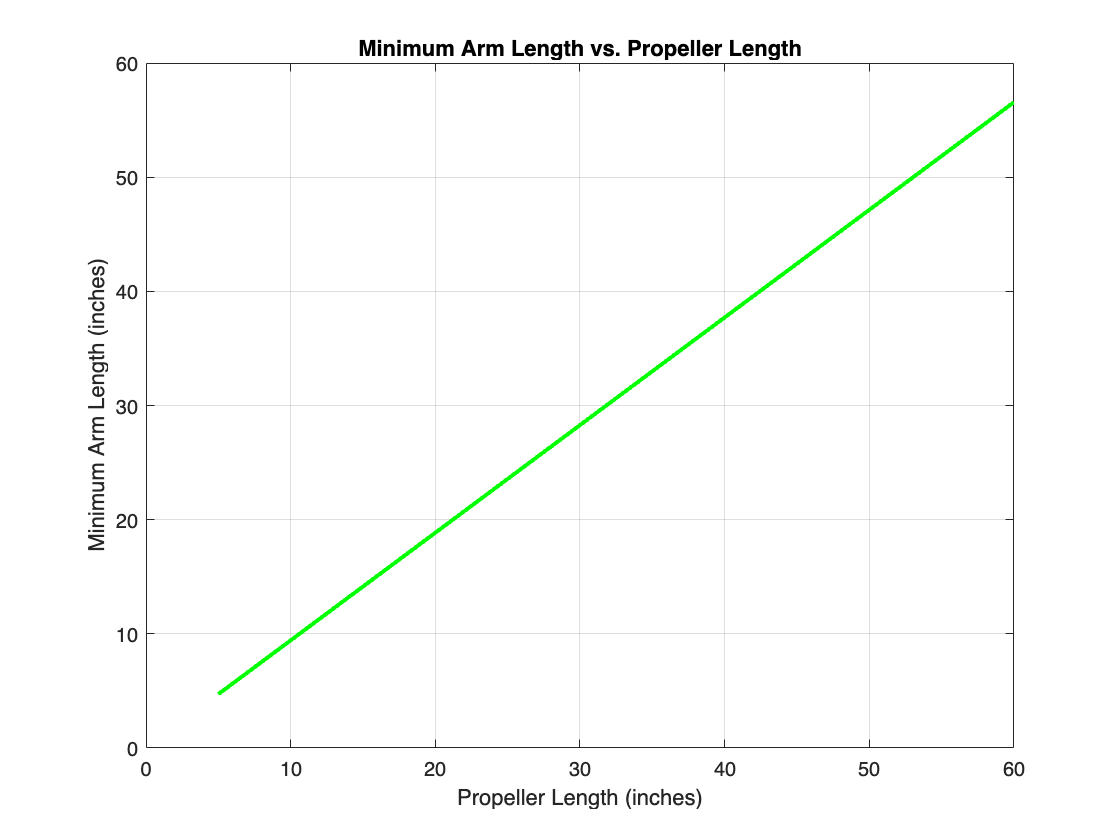

%plotting the minimum arm length, propellor diameter relationship
armvprop

Because we had 4 discrete propellor lengths to choose from (24 inches, 36 inches, 40 inches, 47 inches), we were able to use these values and the above equation for the minimum arm length to calculate the footprint of the airframe. The mounting footprint of the Xoar TA110-20 KV80 motors are a 50mm (~1.9685 inches) diameter circular surface.

The airframe of a large drone like this could easily be manufactured through the machining of a carbon fiber sheet. In order to find the size of this sheet, we derived the equation $\mathrm{side}\;\mathrm{length}=\cos \left(45\right)*\left(2*\mathrm{armlength}+\mathrm{motor}\;\mathrm{mount}\;\mathrm{diameter}\right)$. We ended up selecting the 47 inch diameter propellors for our application as they provided the highest available thrust, giving us the most marging to work within. This led us to find that the airframe could be manufactured from a 54.725 inch square carbon fiber sheet, and we ended up selecting a thickness of 15 mm (~0.5906 inches). We wished to do Finite Element Analysis on the 3D model of our airframe but were unable to get access to the PDE toolbox.